clear;clc

See figure, taken from NASA-TM-2009-215680:

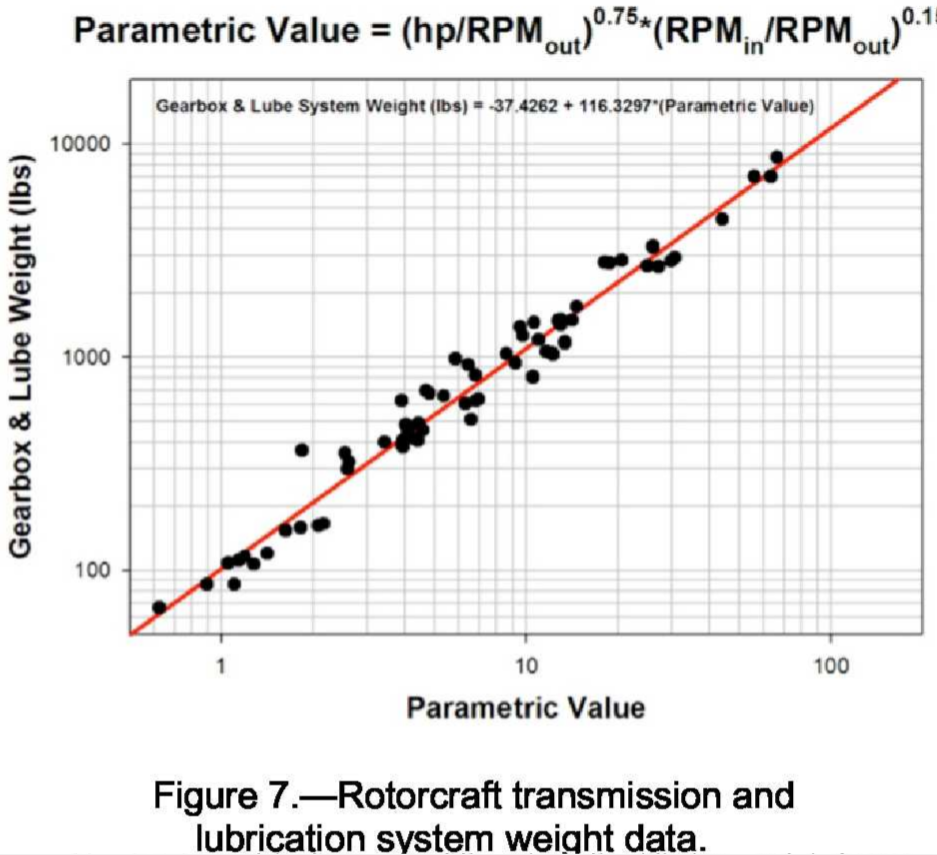

This data was digitized with Engauge Digitizer.

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["x", "Data"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
data = readtable("Fig_from_NASA-TM-2009-215680-cropped.csv", opts);

%% Clear temporary variables
clear opts

Now, we analyze.

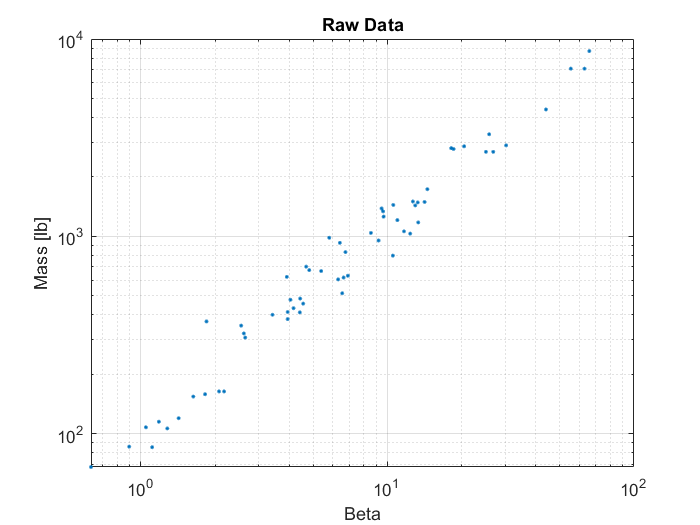

log10_beta = table2array(data(:,"x"));
log10_mass_lb = table2array(data(:,"Data"));
figure
loglog(10.^log10_beta, 10.^log10_mass_lb,".")
grid on
xlabel("Beta")
ylabel("Mass [lb]")
title("Raw Data")

drawnow

And fit it:

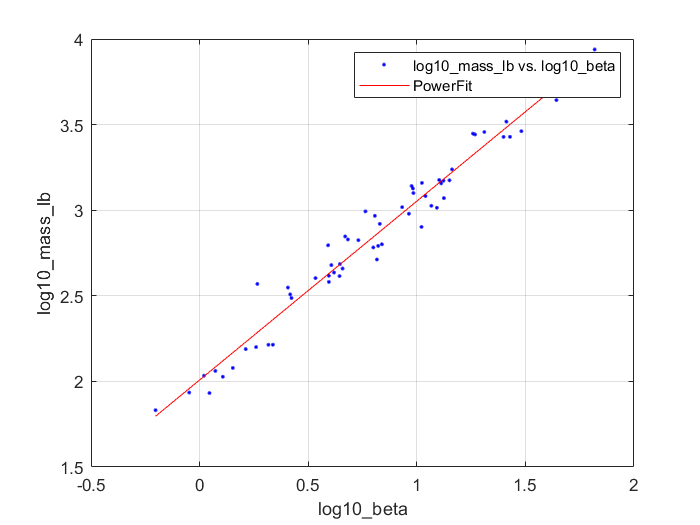

fits =      Linear model Poly1:
     fits(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.045  (0.994, 1.095)
       p2 =       2.008  (1.961, 2.056)

figure
fits = createFit(log10_beta, log10_mass_lb)

fit = fits

fit =      Linear model Poly1:
     fit(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.045  (0.994, 1.095)
       p2 =       2.008  (1.961, 2.056)

Make a shiny plot showing the fit:

figure
betas = logspace(-1, 3, 500)

betas = 	1.0e+03 *

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002


mass_lb_fit = 10.^fit(log10(betas))

mass_lb_fit = 	1.0e+05 *

    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001


loglog(betas, mass_lb_fit)
hold on
loglog(betas, -37.4262 + 116.3297 * betas)
scatter(10.^log10_beta, 10.^log10_mass_lb, ".k")
legend("Our Fit", "Previous Authors' Fit", "Data")
grid on
xlabel("Beta")

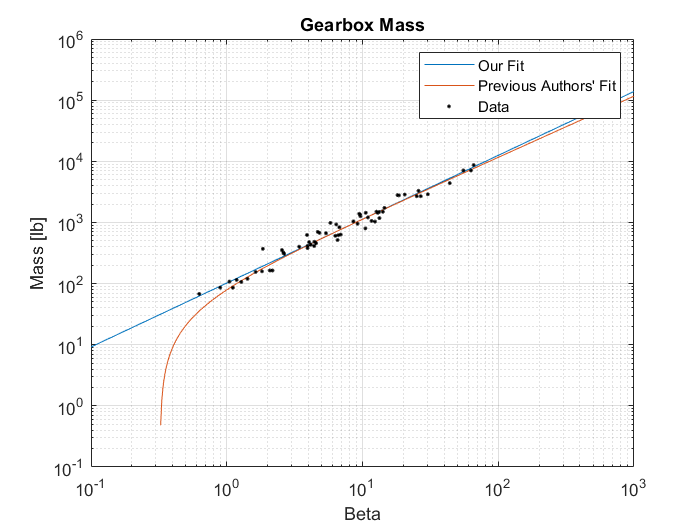

ylabel("Mass [lb]")
title("Gearbox Mass")
saveas(gcf, "gearboxmassfit.svg")

Extract the overall fit; convert it to Python code:

And display it for copy/pasting into Python:

names = coeffnames(fit)

names = 2×1 cell array
    {'p1'}
    {'p2'}

vals = coeffvalues(fit)

vals =     1.0445    2.0084


for i=1:length(names)
    disp(sprintf("%s = %.16f", names{i}, vals(i)))
end

p1 = 1.0445171124733774
p2 = 2.0083615496306910


f=strrep(formula(fit),"^"," ** ");
disp(f)

p1*x + p2
